## Blister

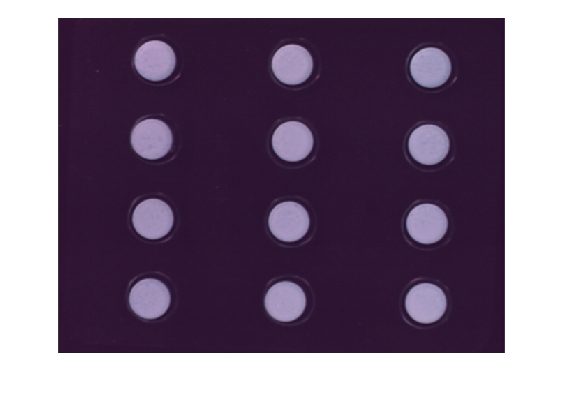

A = imread('Blispac1.tif');
B = imread('Blispac2.tif');
%B = imtranslate(B, [30, -5]); % alineació
imshow(A); 

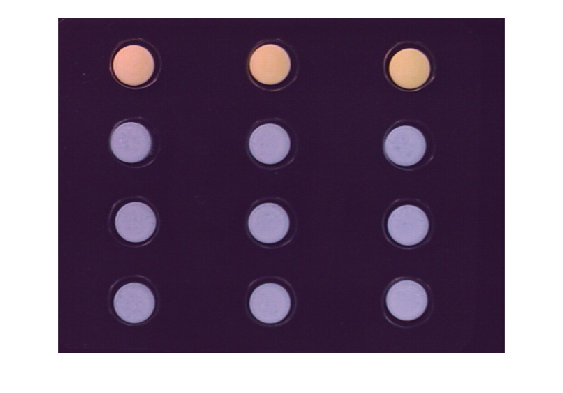

imshow(B);

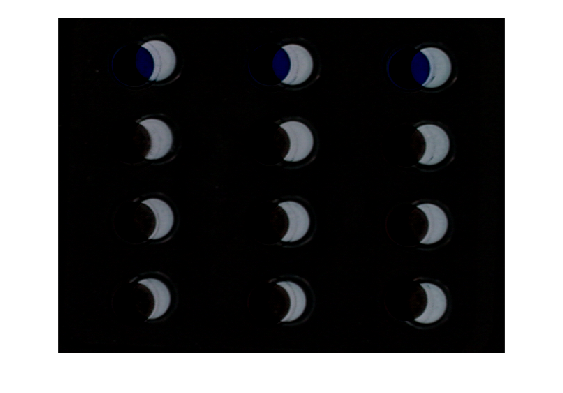

X = abs(A-B);
imshow(X);

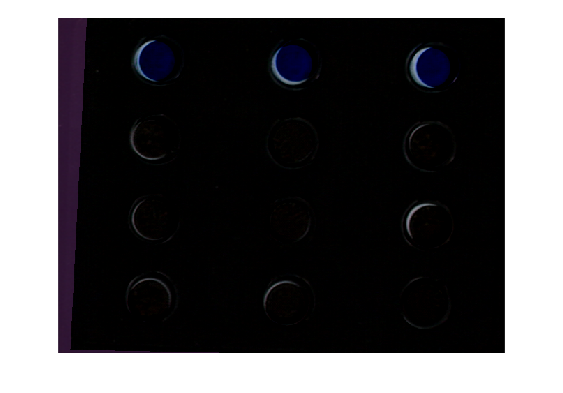

%[x,y] = getpts; % demana els punts
%[i,j] = getpts; %punts de sortida
%x = [107;501;497;105];
%y = [70;73;403;411];
%i = [135;530;524;127];
%j = [62;72;408;405];
x = [107;302;501;105;302;496;109;302;499;105;303;497;];
y = [70;66;73;178;182;183;293;296;297;411;408;403;];
i = [135;339;530;132;368;536;141;315;532;130;327;515;];
j = [62;69;72;176;180;181;290;294;272;398;404;430;];
tform = fitgeotrans([x,y],[i,j],'projective');
J = imwarp(B,tform, "OutputView",imref2d(size(B)));
C = abs(A-J);
imshow(C);


imshow(C);

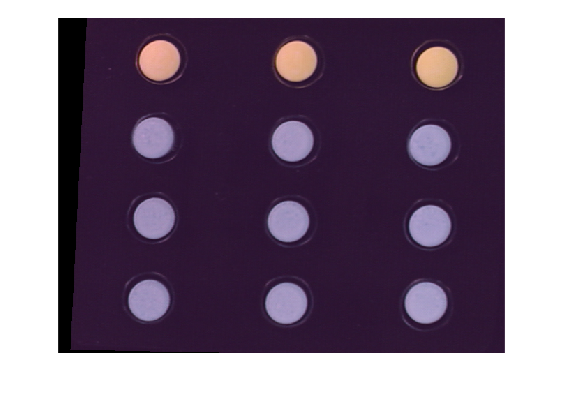

D = C(:,:,3)*7; % augmentem contrast
imshow(J);

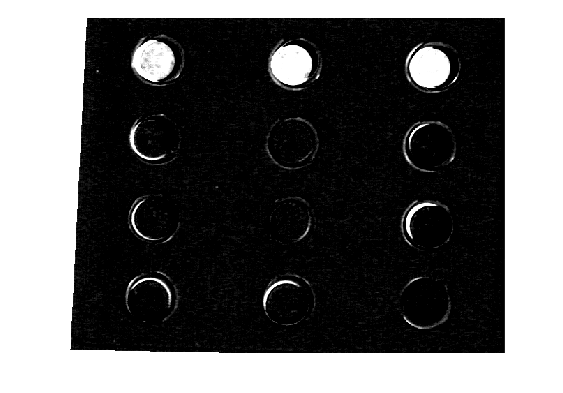

imshow(D);

D (D < 200) = 0;
%D ( D > 0) = 1

D = 480×640 uint8 matrix
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   

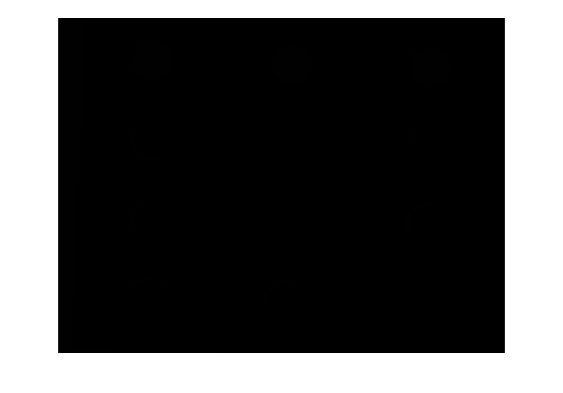

imshow(D);